# **Important Commands**

[syms](https://www.mathworks.com/help/symbolic/syms.html?searchHighlight=syms&s_tid=doc_srchtitle) - Create symbolic variables and functions

syms x y

[simplify](https://www.mathworks.com/help/symbolic/simplify.html?s_tid=doc_ta) - Algebraic simplification

syms x y
y = x^2 + 6*x + 9

$$y = x^{2}+6\,x+9$$

simplify(y)

$$ans = {\left(x+3\right)}^{2}$$

syms x y
y = 2 * (x + 3)^2 / (x^2 + 6*x + 9)

$$y = \frac{2\,{\left(x+3\right)}^{2}}{x^{2}+6\,x+9}$$

simplify(y)

$$ans = 2$$

syms x 
equ = y == 2 * (x + 3)^2 / (x^2 + 6*x + 9)

$$equ = \frac{2\,{\left(x+3\right)}^{2}}{x^{2}+6\,x+9}=\frac{2\,{\left(x+3\right)}^{2}}{x^{2}+6\,x+9}$$

simplify(equ)

$$ans = \mathrm{TRUE}$$

syms y1 y2 x
y1 = (x+1)^2

$$y1 = {\left(x+1\right)}^{2}$$

y2 = x^2 + 2*x + 1

$$y2 = x^{2}+2\,x+1$$

if simplify(y1) == simplify(y2)
    disp('y1 EQUALS y2')
else
    disp('y1 NOT EQUALS y2')
end

y1 EQUALS y2


[expand](https://www.mathworks.com/help/symbolic/mupad_ref/expand.html?s_tid=srchtitle) - multipy out the polynomial

syms x y
y = ( x + 3)^2

$$y = {\left(x+3\right)}^{2}$$

expand(y)

$$ans = x^{2}+6\,x+9$$

syms x y
equ = (x+2)^3 == (x+3)^2

$$equ = {\left(x+2\right)}^{3}={\left(x+3\right)}^{2}$$

expand(equ)

$$ans = x^{3}+6\,x^{2}+12\,x+8=x^{2}+6\,x+9$$

simplify(equ)

$$ans = {\left(x+2\right)}^{3}={\left(x+3\right)}^{2}$$

[solve ](https://www.mathworks.com/help/symbolic/solve.html?s_tid=srchtitle)- Equations and systems solver

solve((x-2),x)

$$ans = 2$$

syms x
eqn = sin(x) == 1;
solx = solve(eqn,x)

$$solx = \frac{\pi }{2}$$

syms x y

equ = x == 2 * y

$$equ = x=2\,y$$


solve(equ, y)

$$ans = \frac{x}{2}$$

 [factor](https://www.mathworks.com/help/symbolic/factor.html?searchHighlight=factor&s_tid=doc_srchtitle) 

syms y x

y = x^2 + 5*x + 6

$$y = x^{2}+5\,x+6$$


factor(y,x)

$$ans = \left(\begin{array}{cc} x+3 & x+2 \end{array}\right)$$


expand((x+3)*(x+2))

$$ans = x^{2}+5\,x+6$$

[collect](https://www.mathworks.com/help/symbolic/collect.html?searchHighlight=collect&s_tid=doc_srchtitle) - Collect coefficient


syms y x z

y = 2*x^2 + 6*x + 9 + x^2 + 2*x*z + z^2

$$y = 3\,x^{2}+2\,x\,z+6\,x+z^{2}+9$$


collect(y,x)

$$ans = 3\,x^{2}+\left(2\,z+6\right)\,x+z^{2}+9$$


collect(y,z)

$$ans = z^{2}+\left(2\,x\right)\,z+3\,x^{2}+6\,x+9$$


syms y x z

equ = y + (x+2)^2 + x + z == (x+3)^2 + (x+z)^2

$$equ = x+y+z+{\left(x+2\right)}^{2}={\left(x+3\right)}^{2}+{\left(x+z\right)}^{2}$$


expand(equ)

$$ans = x^{2}+5\,x+y+z+4=2\,x^{2}+2\,x\,z+6\,x+z^{2}+9$$


collect(equ,x)

$$ans = x^{2}+5\,x+y+z+4=2\,x^{2}+\left(2\,z+6\right)\,x+z^{2}+9$$

[subs](https://www.mathworks.com/help/symbolic/subs.html?searchHighlight=subs&s_tid=doc_srchtitle) - Symbolic substitution

syms a b
y = a + b

$$y = a+b$$

subs(y, a, 4)

$$ans = b+4$$

[poly2sym](https://www.mathworks.com/help/symbolic/poly2sym.html?searchHighlight=poly2sym&s_tid=doc_srchtitle) -  Create symbolic polynomial from vector of coefficients

A = [3 2 9]

A =      3     2     9


y = poly2sym(A,z)

$$y = 3\,z^{2}+2\,z+9$$

[sym2poly](https://www.mathworks.com/help/symbolic/sym2poly.html?searchHighlight=sym2poly&s_tid=doc_srchtitle) - Extract vector of all numeric coefficients, including zeros, from symbolic polynomial

syms x y
y = 3*x^3 + 5*x^2 + 2*x + 9

$$y = 3\,x^{3}+5\,x^{2}+2\,x+9$$

B = sym2poly(y)

B =      3     5     2     9


[plot ](https://www.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=doc_srchtitle)- 2-D line plot

x = [ -3 -2 -1 0 1 2 3]

x =     -3    -2    -1     0     1     2     3


y = x.^2

y =      9     4     1     0     1     4     9


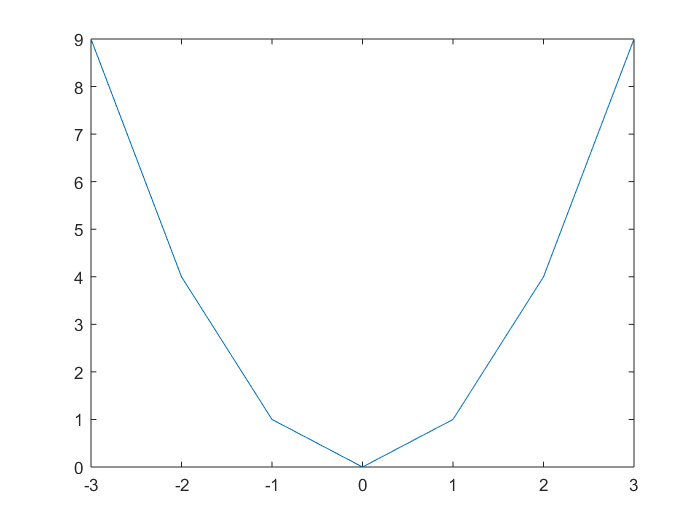

plot(x,y)

x = -5:1:5

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


y = x.^2

y =     25    16     9     4     1     0     1     4     9    16    25


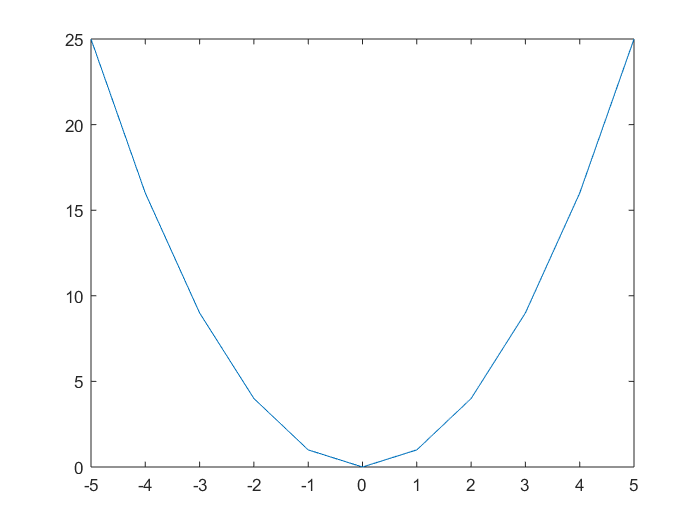


plot(x,y)

Plotting a circle

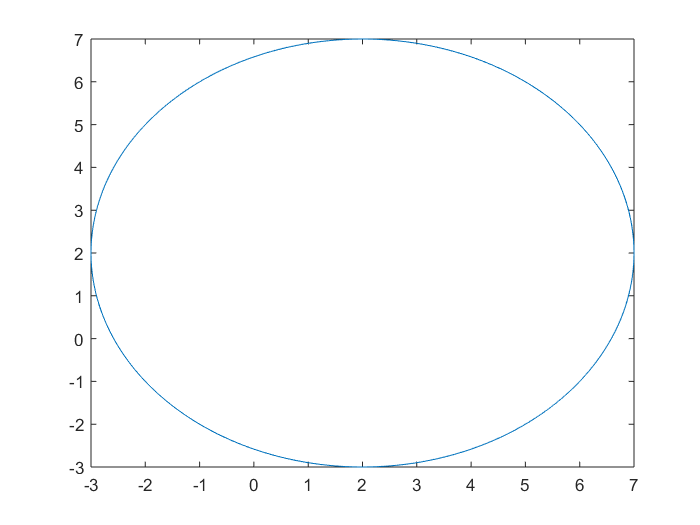

x = 1;
y = 2;
r = 5;
th=0:pi/100:2*pi;
a = r*cos(th)+y;
b = r*sin(th)+y;
plot(a,b)

Plotting many lines on the same plot

x=1:10

x =      1     2     3     4     5     6     7     8     9    10


y1=x

y1 =      1     2     3     4     5     6     7     8     9    10


figure;
plot(x,y1,'r')
title('y VS y'),xlabel('x'),ylabel('y')
y2=2*x

y2 =      2     4     6     8    10    12    14    16    18    20


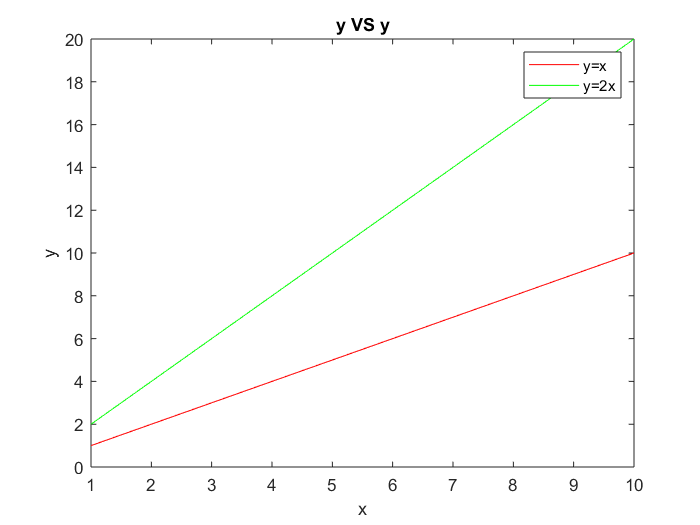

hold on;
plot(x,y2,'g')
hold off;
legend('y=x','y=2x')